# MTH305 Risk Management - Computer Lab 3 - 2025-26

In this lab session, we shall calculate the value at risk (VaR) for a portfolio of stock indices.

It also covers some tutorial questions in week 5 and 6.

Context

- Suppose it is now at the end of day 20080925.

- You are currently holding $4,000, $3,000, $1,000 and $2,000 in four indices, respectively.

- You would calculate the 1-day 99% VaR of this portfolio.

Data

- You are equipped with the daily close price of the four stock indices from 20060807 to 20080925.

Assumptions

- For historical simulation, assume that data from the last few years is a good guide to what will happen over the next day.

- For the model-building approach, assume that the stock returns for the next day are multivariate normal with mean zero.

There are four exercises to be completed.

- Solutions are provided at the end of this file.

- But for some questions that are to be assessed in the coursework, solutions are not provided and please have a try by yourself.

- Feel free to ask questions.

clear
clc
format long

% [dollar_invest]: 4-by-1, dollar amount invested in each index
dollar_invest = [4000, 3000, 1000, 2000]';
V = sum(dollar_invest);

% [weight_stock]: 4-by-1, weight of index in the portfolio
weight_stock = dollar_invest / V;

% VaR parameters
confidence = 0.99;

## 1. import data

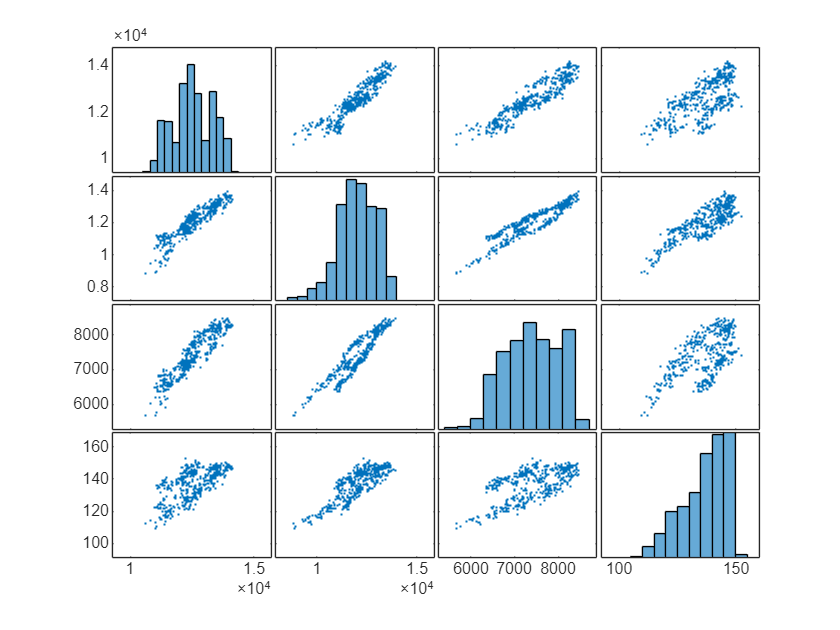

filename = 'W05_demo_historical_simulation.xlsx';
% filename = '../../slides/W5 hitorical simulation/W05_demo_historical_simulation.xlsx';

y = readtable(filename, 'Sheet','1. Data', 'Range','B4:P504');
stock_date = y{:,1};
stock_close = y{:,[3, 7, 11, 15]};
plotmatrix(stock_close)

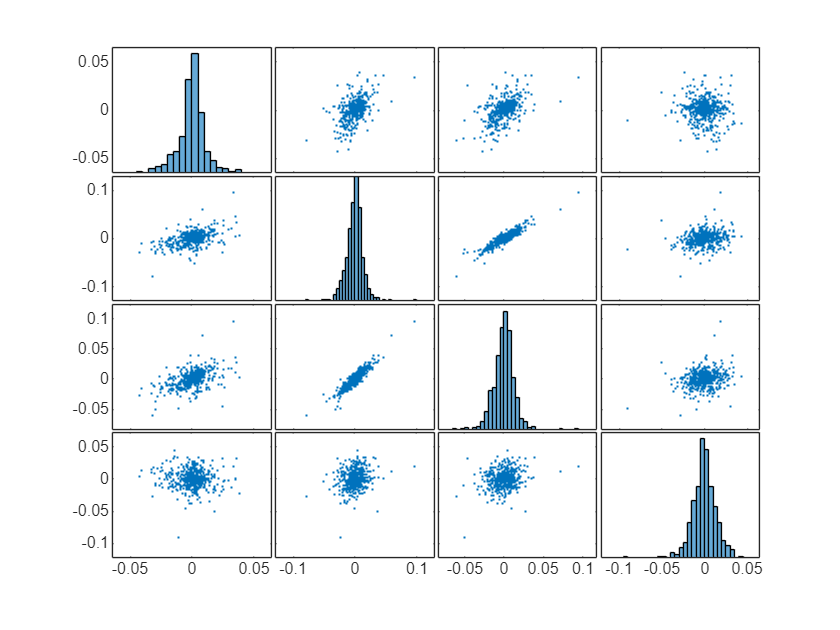

[T, N_stocks] = size(stock_close);   % T = 501days, N_stocks = 4

% [ret_stock]: (T-1)-by-N_stocks, daily stock returns
ret_stock = stock_close(2:end,:) ./ stock_close(1:end-1,:) -1;
plotmatrix(ret_stock)


% [ret_portfolio]: (T-1)-by-1, daily portfolio returns
ret_portfolio = ret_stock * weight_stock;

## 2. VaR -- historical simulation

% number of scenarios
N_scenarios = T-1;

### 2.1 baseline: equal weight on scenarios

% [loss]: (T-1)-by-1, loss given dollar investment V
loss = - V * ret_portfolio;
weight_scenario_ew = ones(N_scenarios, 1) * (1/N_scenarios);

Study the user-defined function [VaR] = VaR_count(loss, weight, confidence) that

- ranks loss scenarios with their weights

- finds the VaR, i.e., the ranked loss whose cumulative weight equals to or just exceeds (1-confidence).

You may implement different rules for finding the VaR, but need to

- know exactly what you are calculating

- be consistent in all calculations, e.g., not using rule 1 for portfolio 1 and rule 2 for portfolio 2.

% call function VaR_count
VaR_sim_ew = VaR_count(loss, weight_scenario_ew, confidence);
disp(VaR_sim_ew)

     2.533849560997946e+02



### 2.2 exponential weight on scenarios

**Exercise 1**

Calculate the exponential weight on scenarios, and calculate VaR by calling the function VaR_count.

[weight_scenario_expw]: N_scenarios-by-1

[VaR_sim_expw]: scalar

The formula for the weight is

$w_i=\frac{\lambda^{n-i}(1-\lambda)}{1-\lambda^n}$.

Be careful: more recent observations are given more weight, not the opposite.

Answer is VaR_sim_expw = 282.2038.

lambda = 0.995;

% Put your code here and replace the random number (randn).
for i = 1:N_scenarios
    weight_scenario_ew(i) = lambda^(N_scenarios-i)*(1-lambda)/(1-lambda^N_scenarios);
end

VaR_sim_expw = VaR_count(loss,weight_scenario_ew,confidence);

disp(VaR_sim_expw)

     2.822038452046129e+02



### 2.3 volatility scaling

Compared with the textbook example of volatility scaling:

- difference: we estimate the volatility of the portfolio return instead of the volatility of each stock index

- same implementation: we set the first estimate of volatility equal to the sample standard deviation of returns.

General steps include:

- estimate GARCH(1,1) model for the volatility of portfolio returns and read parameter estimates

- calculate the model-implied volatilities of portfolio returns

- calculate portfolio losses scaled by volatility

- calculate VaR by calling the function VaR_count.

**Exercise 2**

In the lab and the coursework project, the adjustment is applied to the return of the portfolio return:


$$L_{n+1,p}^{(i)}=-V_{n,p}\cdot \left[r_{i,p}\cdot \frac{\sigma_{n+1,p}}{\sigma_{i,p}}\right],$$


where

- $r_{i,p}$ is the portfolio return over Day $i$

- $\sigma_{n+1,p}$ is the volatility of the portfolio return on Day $n+1$

- $\sigma_{i,p}$ is the volatility of the portfolio return on Day $i$.

For the first estimate of volatility, assume $\sigma_{1}^2$ or $\sigma_{20060808}^2$ is equal to the sample variance of portfolio returns.

Solution not provided -- to be assessed in coursework.

Answer is VaR_sim_vol = 688.7083.

Since different MATLAB versions give slightly different estimates of GARCH parameters, some of you are not able to replicate exactly the answer. Then as a check, you may use the parameters given below and the correct answer is VaR_sim_vol = 527.4665.

- omega_hat = 8e-6;

- beta_hat = 0.85;

- alpha_hat = 0.12;

Mdl = garch(1,1);
EstMdl = estimate(Mdl, ret_portfolio);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                       Value               StandardError           TStatistic               PValue        
                ____________________    ____________________    _________________    _____________________

    Constant    8.40819526596428e-07    1.15381760123197e-06    0.728728289201567        0.466167884680132
    GARCH{1}       0.886565633521468      0.0241888845687145     36.6517782580243    4.28703896632041e-294
    ARCH{1}        0.113434166478532      0.0237436527740328     4.77745221251672     1.77530222567881e-06




% Put your code here and replace the random number (randn).
% Read estimated parameters from EstMdl.
omega_hat = EstMdl.Constant;
beta_hat = EstMdl.GARCH{1,1};
alpha_hat = EstMdl.ARCH{1,1};

% omega_hat = 8e-6;
% beta_hat = 0.85;
% alpha_hat = 0.12;

Var = ones(N_scenarios,1);
Var(1)=var(ret_portfolio);
for i=2:N_scenarios
    Var(i)=omega_hat+alpha_hat*ret_portfolio(i)^2+beta_hat*Var(i-1);
end

var_new=omega_hat+alpha_hat*ret_portfolio(end)^2+beta_hat*Var(end);

for j =1:length(Var)
    weight_scenario_ew(i)=ret_portfolio(i)*sqrt(var_new/Var(i));
end

VaR_sim_expw = VaR_count(loss,weight_scenario_ew,confidence);

disp(VaR_sim_vol)

   1.0e-03 *

   0.000639741972328
   0.001232697499811
  -0.002401210391270
  -0.001139009116532
   0.002897655131141
   0.003928112769727
   0.003999666294753
  -0.000280253940379
  -0.000067988991238
   0.000163122391406
  -0.000421481058456
  -0.001985504106690
  -0.000579335800501
  -0.001624272803801
   0.002730916056713
   0.002498700297880
   0.000224384340191
   0.002739061556514
   0.002533666482577
  -0.004968072033520
  -0.005826278147322
   0.000951754683726
  -0.003515620178320
   0.004148457902041
   0.000982124499084
   0.002247773893761
  -0.001268787996602
  -0.000486183600579
   0.002095382483406
   0.001422684562749
  -0.003258769934664
   0.000017666645974
   0.002849767309078
   0.004030235371685
   0.000456030588117
  -0.001093097021326
   0.002627106753604
   0.000359632178697
   0.001658713822081
   0.003784280095285
  -0.002804533102784
   0.000776019268578
  -0.000567187128789
   0.003416114325438
   0.001643349543277
   0.003046127699153
  -0.002042180689068

## 3. VaR -- model-building approach

What is the model for a portfolio of stocks?

Why do we need the variance-covariance matrix of stocks?

The linear model is


$$\Delta P =\sum_{i=1}^{d}\delta_i \cdot \Delta x_i,$$


where

- $\Delta P$ is the change in value of the portfolio

- $\delta_i$ is the dollar amount invested in asset $i$

- $\Delta x_i$ is the return on asset $i$.

Assuming returns are multivariate normal with mean zero, then $\Delta P$ is also normally distributed with a mean of zero and a variance of


$$\sigma_P^2=\sum_{i=1}^{d}\sum_{j=1}^{d}\delta_i \delta_j Cov_{i,j}=\delta^T C \delta,$$


where

- $Cov_{i,j}$ is the covariance between return on asset $i$ and the return on asset $j$

- 
$$\delta = [\delta_1,\delta_2,\dots,\delta_d]^T$$


- $C$ is the variance-covariance matrix of returns.

The VaR of the portfolio with a confidence level of $X$ is


$$\text{VaR}_{X}=N^{-1}(X) \cdot \sigma_P,$$


where $N^{-1}$ is inverse standard normal.

### 3.1 delta dollar exposure of portfolio

delta = dollar_invest;

### 3.2 VaR -- variance-covariance matrix -- equal weight

[varcov_ew]: N_stocks-by-N_stocks, sample variance-covariance matrix of stocks

% Note the estimate of variance/covariance by function 'cov' is
% sample variance/covariance normalised by (number of observations - 1)
n = T-1;   % n = 500
varcov_ew = cov(ret_stock) * (n-1)/n;   % population variance to replicate Excel result

**Exercise 3**

Calculate the variance of change in portfolio value and the VaR of the portfolio.

Answer is VaR_mb_ew = 217.7570.

% Put your code here and replace the random number (randn).
variance_portfolio_ew = randn(1,1);
VaR_mb_ew = randn(1,1);

disp(VaR_mb_ew)

   1.804493771724187



### 3.3 VaR -- variance-covariance matrix -- ewma

**Exercise 4**

Calculate VaR with EWMA updated variance-covariance matrix.

For the first estimate of variance-covariance matrix, assume:

vcv_20060808 = population variances and covariances of stock returns.

Solution is not provided -- to be assessed in coursework.

Answer is VaR_mb_ewma = 471.0252.

lambda = 0.94;

% Put your code here and replace the random number (randn).
VaR_mb_ewma = randn(1,1);

disp(VaR_mb_ewma)

  -0.723121479570418



## 4. VaR -- extreme value theory

**Exercise 5**

Study the webpage [https://www.mathworks.com/help/stats/generalized-pareto-distribution.html](https://www.mathworks.com/help/stats/generalized-pareto-distribution.html)

Calculate the input to the function gpfit.

% threshold, e.g., 160, prctile(loss, 95)
u = 160;

% Put your code here and replace the random number (gprnd).
loss_y = gprnd(0.4, 1, 0, 100, 1);

% estimate distribution parameters
paramEsts = gpfit(loss_y);
xi = paramEsts(1);
beta = paramEsts(2);

% calculate VaR
nu = size(loss_y, 1);
n = T-1;
VaR_evt = u+beta/xi*( (n/nu*(1-confidence))^(-xi) -1 );
disp(VaR_evt)

     1.653378099886106e+02



## Solutions

% % exercise 1
% weight_scenario_expw = NaN(N_scenarios, 1);
% for i = 1 : N_scenarios
%     weight_scenario_expw(i) = lambda^(N_scenarios-i) *(1-lambda) / (1-lambda^N_scenarios);
% end
% VaR_sim_expw = VaR_count(loss, weight_scenario_expw, confidence);


% % exercise 3
% variance_portfolio_ew = delta' * varcov_ew * delta;
% VaR_mb_ew = norminv(confidence) * sqrt(variance_portfolio_ew);


% % exercise 5
% loss_y = loss-u;
% loss_y = loss_y(loss_y>0);